# 줄거리 소재에 따른 영화의 수익 예측

## ◆ 목표 : 특정 장르에서 어떤 줄거리 소재를 선택해야

## 영화의 흥행도 및 수익율을 창출해낼 수 있는가

## TMDB의 Raw Data

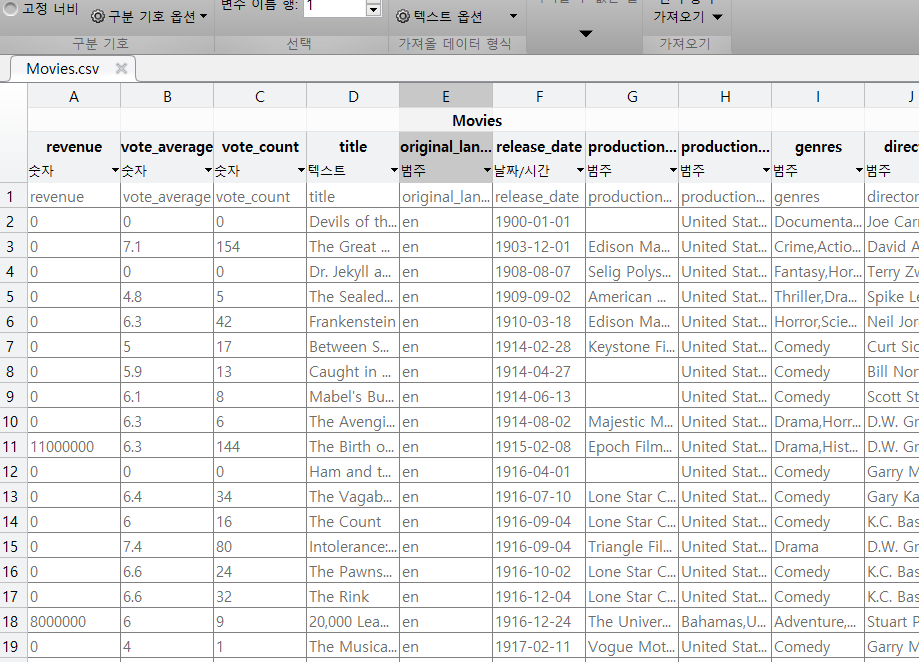

- '모든 장르의 Word Cloud 시각화'

## 텍스트 파일이서 데이터 가져오기

1. 변수 초기화

filename = 'C:\Users\정상아\Desktop\2학년\고급컴퓨터수학\Movies.csv';
delimiter = ',';
startRow = 2;

2. 데이터 열을 텍스트로 읽는다.

formatSpec = '%q%q%q%q%*q%q%*q%*q%q%[^\n\r]';

3. 텍스트 파일을 연다.

fileID = fopen(filename,'r');

4. 형식에 따라  데이터 열을 읽는다.

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');

5. 텍스트 파일을 닫는다.

fclose(fileID);

## 숫자형 텍스트가 있는 열의 내용을 숫자로 변환하기

1. 숫자형이 아닌 텍스트를 NaN으로 바꾼다.

raw = repmat({''},length(dataArray{1}),length(dataArray)-1);
for col=1:length(dataArray)-1
    raw(1:length(dataArray{col}),col) = mat2cell(dataArray{col}, ones(length(dataArray{col}), 1));
end
numericData = NaN(size(dataArray{1},1),size(dataArray,2));

2. 입력 셀형 배열의 텍스트를 숫자로 변환하고, 숫자형이 아닌 텍스트는 NaN으로 바꾼다.

for col=[1,2,3]
     rawData = dataArray{col};
    for row=1:size(rawData, 1)

3. 숫자형이 아닌 접두사 및 접미사를 검색하고 제거하는 정규 표현식을 만든다.

    regexstr = '(?<prefix>.*?)(?<numbers>([-]*(\d+[\,]*)+[\.]{0,1}\d*[eEdD]{0,1}[-+]*\d*[i]{0,1})|([-]*(\d+[\,]*)*[\.]{1,1}\d+[eEdD]{0,1}[-+]*\d*[i]{0,1}))(?<suffix>.*)';
        try
            result = regexp(rawData(row), regexstr, 'names');
            numbers = result.numbers;

4. 천 단위가 아닌 위치에서 쉼표 검색한다.

      invalidThousandsSeparator = false;
            if numbers.contains(',')
                thousandsRegExp = '^[-/+]*\d+?(\,\d{3})*\.{0,1}\d*$';
                if isempty(regexp(numbers, thousandsRegExp, 'once'))
                    numbers = NaN;
                    invalidThousandsSeparator = true;
                end
            end

5. 숫자형 텍스트를 숫자로 변환한다.

             if ~invalidThousandsSeparator
                numbers = textscan(char(strrep(numbers, ',', '')), '%f');
                numericData(row, col) = numbers{1};
                raw{row, col} = numbers{1};
            end
        catch
            raw{row, col} = rawData{row};
        end
    end
end

6. 지정된 날짜 형식을 사용해 날짜가 있는 열의 내용을 MATLAB datatime형으로 변환한다.

try
    dates{5} = datetime(dataArray{5}, 'Format', 'yyyy-MM-dd', 'InputFormat', 'yyyy-MM-dd');
catch
    try
        % 따옴표로 묶인 날짜 처리
        dataArray{5} = cellfun(@(x) x(2:end-1), dataArray{5}, 'UniformOutput', false);
        dates{5} = datetime(dataArray{5}, 'Format', 'yyyy-MM-dd', 'InputFormat', 'yyyy-MM-dd');
    catch
        dates{5} = repmat(datetime([NaN NaN NaN]), size(dataArray{5}));
    end
end

dates = dates(:,5);

7. 데이터를 숫자형 열과 String형 열로 분할한다.

rawNumericColumns = raw(:, [1,2,3]);
rawStringColumns = string(raw(:, [4,6]));

8. 숫자형이 아닌 셀을 NaN으로 바꾼다.

R = cellfun(@(x) ~isnumeric(x) && ~islogical(x),rawNumericColumns); % 숫자형이 아닌 셀 찾기
rawNumericColumns(R) = {NaN}; % 숫자형이 아닌 셀 바꾸기

9. <Undefined>를 포함하는 텍스트가 <Undefined> categorical형으로 변환되었는지 확인한다.

idx = (rawStringColumns(:, 2) == "<undefined>");
rawStringColumns(idx, 2) = "";

## 가져온 배열을 열 변수 이름으로 할당하기

revenue1 : 영화 별 수익

vote_average1 : 영화 별 평점

vote_count1 : 영화 별 관람수

title1 : 영화 제목

release_date1 : 영화 개봉일

genres1 : 영화 장르

revenue1 = cell2mat(rawNumericColumns(:, 1));
vote_average1 = cell2mat(rawNumericColumns(:, 2));
vote_count1 = cell2mat(rawNumericColumns(:, 3));
title1 = rawStringColumns(:, 1);
release_date1 = dates{:, 1};
genres1 = rawStringColumns(:, 2);

for i=1:size(revenue1,1)
    if(revenue1(i,1)==0)
        revenue1(i,1)=NaN;
    end
end

k=1;

while ((release_date1(1,1)<datetime(1980,01,01)))
    
    revenue1(1)=[];
    vote_average1(1)=[];
    vote_count1(1)=[];
    title1(1)=[];
    release_date1(1)=[];
    genres1(1)=[];
    
end

임시 변수 지우기

clearvars filename delimiter startRow formatSpec fileID dataArray ans raw col numericData rawData row regexstr result numbers invalidThousandsSeparator thousandsRegExp dates blankDates anyBlankDates invalidDates anyInvalidDates rawNumericColumns rawStringColumns R idx;

## 텍스트 파일에서 데이터 가져오기

1. 변수 초기화

filename = 'movies_metadata_WITH_KEYWORDS.csv';
delimiter = ',';

2. 데이터 열을 텍스트로 읽는다.

formatSpec = '%*q%*q%q%q%*q%*q%q%*q%*q%*q%*q%q%*q%*q%*q%*q%q%*q%*q%*q%*q%*q%*q%q%q%[^\n\r]';

3. 텍스트 파일을 연다.

fileID = fopen(filename,'r');

4. 형식에 따라 데이터 열을 읽는다.

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string',  'ReturnOnError', false);

5. 텍스트 파일을 닫는다.

fclose(fileID);

## 숫자형 텍스트가 있는 열의 내용을 숫자로 변환하기.

1 숫자형 텍스트가 있는 열의 내용을 숫자로 변환하고, 숫자형이 아닌 텍스트를 NaN으로 바꾼다.

raw = repmat({''},length(dataArray{1}),length(dataArray)-1);
for col=1:length(dataArray)-1
    raw(1:length(dataArray{col}),col) = mat2cell(dataArray{col}, ones(length(dataArray{col}), 1));
end
numericData = NaN(size(dataArray{1},1),size(dataArray,2));

2. 입력 셀형 배열의 텍스트를 숫자로 변환하고, 숫자형이 아닌 텍스트는 NaN으로 바꾼다.

for col=[1,4,5,6,7]
    rawData = dataArray{col};
    for row=1:size(rawData, 1)

3. 숫자형이 아닌 접두사 및 접미사를 검색하고 제거하는 정규 표현식을 만든다.

        regexstr = '(?<prefix>.*?)(?<numbers>([-]*(\d+[\,]*)+[\.]{0,1}\d*[eEdD]{0,1}[-+]*\d*[i]{0,1})|([-]*(\d+[\,]*)*[\.]{1,1}\d+[eEdD]{0,1}[-+]*\d*[i]{0,1}))(?<suffix>.*)';
        try
            result = regexp(rawData(row), regexstr, 'names');
            numbers = result.numbers;

4. 천 단위가 아닌 위치에서 쉼표를 검색하고, 숫자형 텍스트를 숫자로 변환한다.

             invalidThousandsSeparator = false;
            if numbers.contains(',')
                thousandsRegExp = '^[-/+]*\d+?(\,\d{3})*\.{0,1}\d*$';
                if isempty(regexp(numbers, thousandsRegExp, 'once'))
                    numbers = NaN;
                    invalidThousandsSeparator = true;
                end
            end
            if ~invalidThousandsSeparator
                numbers = textscan(char(strrep(numbers, ',', '')), '%f');
                numericData(row, col) = numbers{1};
                raw{row, col} = numbers{1};
            end
        catch
            raw{row, col} = rawData{row};
        end
    end
end

5. 데이터를 숫자형 열과 String형 열로 분할한다.

rawNumericColumns = raw(:, [1,4,5,6,7]);
rawStringColumns = string(raw(:, [2,3]));

6. 숫자형이 아닌 셀을 NaN으로 바꾼다.

R = cellfun(@(x) ~isnumeric(x) && ~islogical(x),rawNumericColumns); % 숫자형이 아닌 셀 찾기
rawNumericColumns(R) = {NaN}; % 숫자형이 아닌 셀 바꾸기

7. <undefined>를 포함하는 텍스트가 <undefined> categorical형으로 제대로 변환되었는지 확인한다.

idx = (rawStringColumns(:, 1) == "<undefined>");
rawStringColumns(idx, 1) = "";

8. 가져온 배열을 열 변수 이름으로 할당한다.

    budget : 영화 별 예산

    genres : 영화 장르

    keywords : 영화 별 키워드

    popularity : 영화 별 흥행도

    revenue = 영화 수익

    vote_average : 영화 별 평점

    vote_count : 영화 별 관람수

budget = cell2mat(rawNumericColumns(:, 1));
genres = rawStringColumns(:, 1);
keywords = rawStringColumns(:, 2);
popularity = cell2mat(rawNumericColumns(:, 2));
revenue = cell2mat(rawNumericColumns(:, 3));
vote_average = cell2mat(rawNumericColumns(:, 4));
vote_count = cell2mat(rawNumericColumns(:, 5));

9. 임시 변수를 지운다.

clearvars filename delimiter formatSpec fileID dataArray ans raw col numericData rawData row regexstr result numbers invalidThousandsSeparator thousandsRegExp rawNumericColumns rawStringColumns R idx;

#### ▶ 예시로 장르를 범죄로 선정한다.

WantGenre = "Crime";
G=["Action";"Adventure";"Comedy";"Crime";"Drama";"Fantasy";"Family";"Horror";"Romance";"Thriller";"Science"];
Gindex=0;

for i=1:length(G)
    if(G(i,1)==WantGenre)
        Gindex=i;
    end
end

## ◆ 장르 별 수익 분석

1. 토큰화된 문서에서 빈도수에 따른 영화 장르를 선별한다.

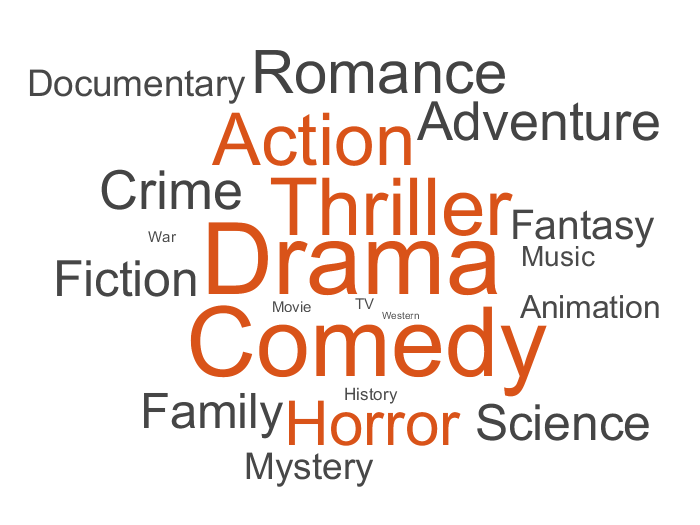

bag1=bagOfWords(tokenizedDocument(replace(genres1,","," ")));
bag1.wordcloud;

- 월별에 따른 각 장르의 수익평균

▶ Crime

CRcount=zeros(12,1);
CRtmp=zeros(size(genres1,1),1);
CRdate=datetime.empty;
CRrevenue=double.empty;
CRMonthR=zeros(12,1);
CRavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Crime'))
        CRtmp(i,1)=1;
        CRdate=[CRdate;release_date1(i,1)];
        CRrevenue=[CRrevenue;revenue1(i,1)];
        if(~isnan(revenue1(i,1)))
            CRcount(CRdate(end,1).Month,1)=CRcount(CRdate(end,1).Month,1)+1;
        end
    end
    
end

for i=1:size(CRdate,1)
    if(~isnan(CRrevenue(i,1)))
        CRMonthR(CRdate(i,1).Month,1)=CRMonthR(CRdate(i,1).Month,1)+CRrevenue(i,1);
    end
end

for i=1:12
    CRavgR(i,1)=CRMonthR(i,1)/CRcount(i,1);
end

▶ Adventure

ADcount=zeros(12,1);
ADtmp=zeros(size(genres1,1),1);
ADdate=datetime.empty;
ADrevenue=double.empty;
ADMonthR=zeros(12,1);
ADavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Adventure'))
        ADtmp(i,1)=1;
        ADdate=[ADdate;release_date1(i,1)];
        ADrevenue=[ADrevenue;revenue1(i,1)];
        
        if(~isnan(revenue1(i,1)))
            ADcount(ADdate(end,1).Month,1)=ADcount(ADdate(end,1).Month,1)+1;
        end
    end
end

for i=1:size(ADdate,1)
    if(~isnan(ADrevenue(i,1)))
        ADMonthR(ADdate(i,1).Month,1)=ADMonthR(ADdate(i,1).Month,1)+ADrevenue(i,1);
    end
end

for i=1:12
    ADavgR(i,1)=ADMonthR(i,1)/ADcount(i,1);
end

▶ Fantasy

Fcount=zeros(12,1);
Ftmp=zeros(size(genres1,1),1);
Fdate=datetime.empty;
Frevenue=double.empty;
FMonthR=zeros(12,1);
FavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Fantasy'))
        Ftmp(i,1)=1;
        Fdate=[Fdate;release_date1(i,1)];
        Frevenue=[Frevenue;revenue1(i,1)];
        
        if(~isnan(revenue1(i,1)))
            Fcount(Fdate(end,1).Month,1)=Fcount(Fdate(end,1).Month,1)+1;
        end
    end
end

for i=1:size(Fdate,1)
    if(~isnan(Frevenue(i,1)))
        FMonthR(Fdate(i,1).Month,1)=FMonthR(Fdate(i,1).Month,1)+Frevenue(i,1);
    end
end
for i=1:12
    FavgR(i,1)=FMonthR(i,1)/Fcount(i,1);
end

▶ Horror

Hcount=zeros(12,1);
Htmp=zeros(size(genres1,1),1);
Hdate=datetime.empty;
Hrevenue=double.empty;
HMonthR=zeros(12,1);
HavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Horror'))
        Htmp(i,1)=1;
        Hdate=[Hdate;release_date1(i,1)];
        Hrevenue=[Hrevenue;revenue1(i,1)];
        
        if(~isnan(revenue1(i,1)))
            Hcount(Hdate(end,1).Month,1)=Hcount(Hdate(end,1).Month,1)+1;
        end
        
        
    end
end

for i=1:size(Hdate,1)
    if (~isnan(Hrevenue(i,1)))
        HMonthR(Hdate(i,1).Month,1)=HMonthR(Hdate(i,1).Month,1)+Hrevenue(i,1);
    end
end
for i=1:12
    HavgR(i,1)=HMonthR(i,1)/Hcount(i,1);
end

▶ Science

Scicount=zeros(12,1);
Scitmp=zeros(size(genres1,1),1);
Scidate=datetime.empty;
Scirevenue=double.empty;
SciMonthR=zeros(12,1);
SciavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Science'))
        Scitmp(i,1)=1;
        Scidate=[Scidate;release_date1(i,1)];
        Scirevenue=[Scirevenue;revenue1(i,1)];
        
        if(~isnan(revenue1(i,1)))
            Scicount(Scidate(end,1).Month,1)=Scicount(Scidate(end,1).Month,1)+1;
        end
    end
end

for i=1:size(Scidate,1)
    if(~isnan(Scirevenue(i,1)))
        SciMonthR(Scidate(i,1).Month,1)=SciMonthR(Scidate(i,1).Month,1)+Scirevenue(i,1);
    end
end
for i=1:12
    SciavgR(i,1)=SciMonthR(i,1)/Scicount(i,1);
end

▶ Family

FMcount=zeros(12,1);
FMtmp=zeros(size(genres1,1),1);
FMdate=datetime.empty;
FMrevenue=double.empty;
FMMonthR=zeros(12,1);
FMavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Family'))
        FMtmp(i,1)=1;
        FMdate=[FMdate;release_date1(i,1)];
        FMrevenue=[FMrevenue;revenue1(i,1)];
        
        
        if(~isnan(revenue1(i,1)))
            FMcount(FMdate(end,1).Month,1)=FMcount(FMdate(end,1).Month,1)+1;
        end
        
        
    end
end

for i=1:size(FMdate,1)
    if(~isnan(FMrevenue(i,1)))
        FMMonthR(FMdate(i,1).Month,1)=FMMonthR(FMdate(i,1).Month,1)+FMrevenue(i,1);
    end
end
for i=1:12
    FMavgR(i,1)=FMMonthR(i,1)/FMcount(i,1);
end

▶ Drama

Dcount=zeros(12,1);
Dtmp=zeros(size(genres1,1),1);
Ddate=datetime.empty;
Drevenue=double.empty;
DMonthR=zeros(12,1);
DavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Drama'))
        Dtmp(i,1)=1;
        Ddate=[Ddate;release_date1(i,1)];
        Drevenue=[Drevenue;revenue1(i,1)];
        %       DMonthR(Ddate(i,1).Month,1)=DMonthR(Ddate(i,1).Month,1)+Drevenue(i,1);
        
        if(~isnan(revenue1(i,1)))
            Dcount(Ddate(end,1).Month,1)=Dcount(Ddate(end,1).Month,1)+1;
        end
        
    end
end

for i=1:size(Ddate,1)
    if(~isnan(Drevenue(i,1)))
        DMonthR(Ddate(i,1).Month,1)=DMonthR(Ddate(i,1).Month,1)+Drevenue(i,1);
    end
end

for i=1:12
    DavgR(i,1)=DMonthR(i,1)/Dcount(i,1);
end

▶ Comedy

Ccount=zeros(12,1);
Ctmp=zeros(size(genres1,1),1);
Cdate=datetime.empty;
Crevenue=double.empty;
CMonthR=zeros(12,1);
CavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Comedy'))
        Ctmp(i,1)=1;
        Cdate=[Cdate;release_date1(i,1)];
        Crevenue=[Crevenue;revenue1(i,1)];
        
        if(~isnan(revenue1(i,1)))
            Ccount(Cdate(end,1).Month,1)=Ccount(Cdate(end,1).Month,1)+1;
        end
        
        
    end
end

for i=1:size(Cdate,1)
    if(~isnan(Crevenue(i,1)))
        CMonthR(Cdate(i,1).Month,1)=CMonthR(Cdate(i,1).Month,1)+Crevenue(i,1);
    end
end

for i=1:12
    CavgR(i,1)=CMonthR(i,1)/Ccount(i,1);
end

▶ Thriller

Tcount=zeros(12,1);
Ttmp=zeros(size(genres1,1),1);
Tdate=datetime.empty;
Trevenue=double.empty;
TMonthR=zeros(12,1);
TavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Thriller'))
        Ttmp(i,1)=1;
        Tdate=[Tdate;release_date1(i,1)];
        Trevenue=[Trevenue;revenue1(i,1)];
        
        if(~(isnan(revenue1(i,1))))
            Tcount(Tdate(end,1).Month,1)=Tcount(Tdate(end,1).Month,1)+1;
        end
        
        
    end
end

for i=1:size(Tdate,1)
    if(~isnan(Trevenue(i,1)))
        TMonthR(Tdate(i,1).Month,1)=TMonthR(Tdate(i,1).Month,1)+Trevenue(i,1);
    end
end

for i=1:12
    TavgR(i,1)=TMonthR(i,1)/Tcount(i,1);
end

▶ Action

Acount=zeros(12,1);
Atmp=zeros(size(genres1,1),1);
Adate=datetime.empty;
Arevenue=double.empty;
AMonthR=zeros(12,1);
AavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Action'))
        Atmp(i,1)=1;
        Adate=[Adate;release_date1(i,1)];
        Arevenue=[Arevenue;revenue1(i,1)];
        
        if(~isnan(revenue1(i,1)))
            Acount(Adate(end,1).Month,1)=Acount(Adate(end,1).Month,1)+1;
        end
        
        
    end
end

for i=1:size(Adate,1)
    if(~isnan(Arevenue(i,1)))
        
        AMonthR(Adate(i,1).Month,1)=AMonthR(Adate(i,1).Month,1)+Arevenue(i,1);
    end
end

for i=1:12
    AavgR(i,1)=AMonthR(i,1)/Acount(i,1);
end

▶ Romance

Rcount=zeros(12,1);
Rtmp=zeros(size(genres1,1),1);
Rdate=datetime.empty;
Rrevenue=double.empty;
RMonthR=zeros(12,1);
RavgR=zeros(12,1);
for i=1:size(genres1,1)
    if(strfind(genres1(i,1),'Romance'))
        Rtmp(i,1)=1;
        Rdate=[Rdate;release_date1(i,1)];
        Rrevenue=[Rrevenue;revenue1(i,1)];
        
        if(isnan(revenue1(i,1)))
            Rcount(Rdate(end,1).Month,1)=Rcount(Rdate(end,1).Month,1)+1;
        end
        
        
    end
end

for i=1:size(Rdate,1)
    if(~isnan(Rrevenue(i,1)))
        RMonthR(Rdate(i,1).Month,1)=RMonthR(Rdate(i,1).Month,1)+Rrevenue(i,1);
    end
end

for i=1:12
    RavgR(i,1)=RMonthR(i,1)/Rcount(i,1);
end

2. 각 장르별 월별 평균 수익을 정규화한다.

rNorA=normalize(AMonthR);
rNorAD=normalize(ADMonthR);
rNorC=normalize(CMonthR);
rNorCR=normalize(CRMonthR);
rNorD=normalize(DMonthR);
rNorF=normalize(FMonthR);
rNorFM=normalize(FMMonthR);
rNorH=normalize(HMonthR);
rNorR=normalize(RMonthR);
rNorT=normalize(TMonthR);
rNorSci=normalize(SciMonthR);

NoravgA=normalize(AavgR);
NoravgAD=normalize(ADavgR);
NoravgC=normalize(CavgR);
NoravgCR=normalize(CRavgR);
NoravgD=normalize(DavgR);
NoravgF=normalize(FavgR);
NoravgFM=normalize(FMavgR);
NoravgH=normalize(HavgR);
NoravgR=normalize(RavgR);
NoravgT=normalize(TavgR);
NoravgSci=normalize(SciavgR);

AVGs=[AavgR,ADavgR,CavgR,CRavgR,DavgR,FavgR,FMavgR,HavgR,RavgR,TavgR,SciavgR];
NAVGs=[NoravgA,NoravgAD,NoravgC,NoravgCR,NoravgD,NoravgF,NoravgFM,NoravgH,NoravgR,NoravgT,NoravgSci];

clear title;

3. 각 장르에 따른 월별 평균 수익

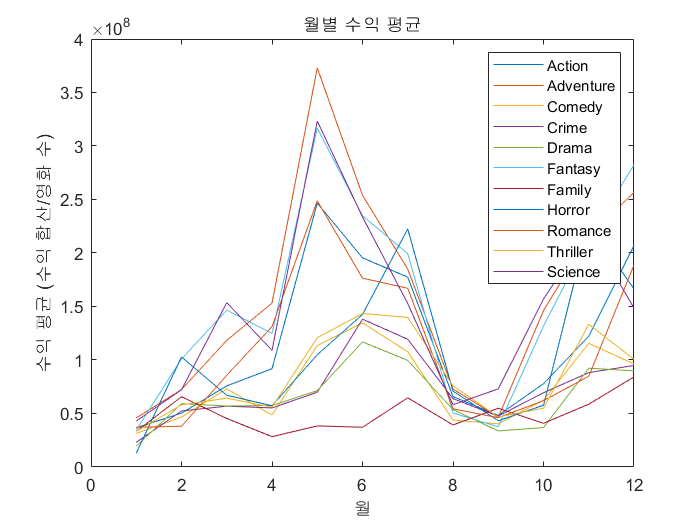

figure
plot(AavgR,'DisplayName','AavgR');hold on;plot(ADavgR,'DisplayName','ADavgR');plot(CavgR,'DisplayName','CavgR');plot(CRavgR,'DisplayName','CRavgR');plot(DavgR,'DisplayName','DavgR');plot(FavgR,'DisplayName','FavgR');plot(HavgR,'DisplayName','HavgR');plot(RavgR,'DisplayName','RavgR');plot(SciavgR,'DisplayName','SciavgR');plot(TavgR,'DisplayName','TavgR');plot(FMavgR,'DisplayName','FMavgR');
title('월별 수익 평균');
xlabel('월') 
ylabel('수익 평균 (수익 합산/영화 수)')
legend('Action','Adventure','Comedy','Crime','Drama','Fantasy','Family','Horror','Romance','Thriller','Science')
hold off;

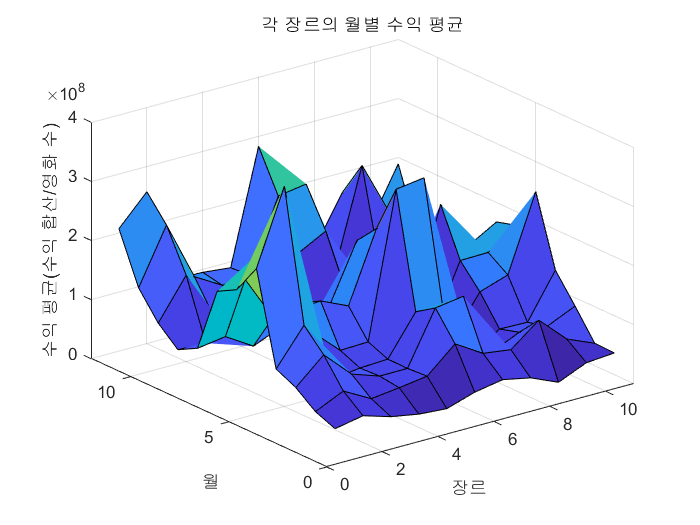


figure
surf(AVGs);
hold on;
title('각 장르의 월별 수익 평균');
xlabel('장르')
ylabel('월') 
zlabel('수익 평균(수익 합산/영화 수)')
hold off;

4. 각 장르에 따른 정규화된 월별 평균 수익

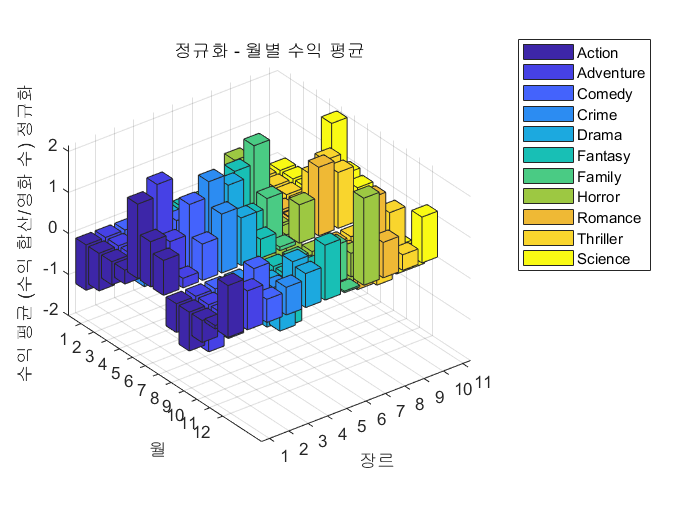

figure
bar3(NAVGs,0.8);hold on;
title('정규화 - 월별 수익 평균');
ylabel('월')
xlabel('장르')
zlabel('수익 평균 (수익 합산/영화 수) 정규화 ')
legend('Action','Adventure','Comedy','Crime','Drama','Fantasy','Family','Horror','Romance','Thriller','Science')
hold off;

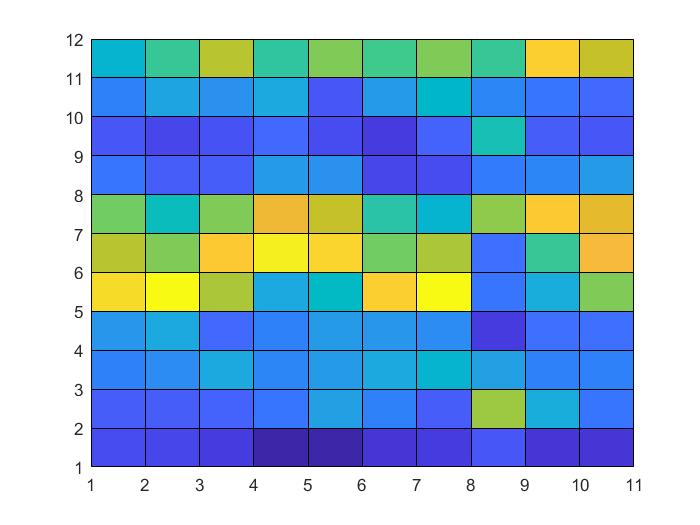


figure
pcolor(NAVGs);

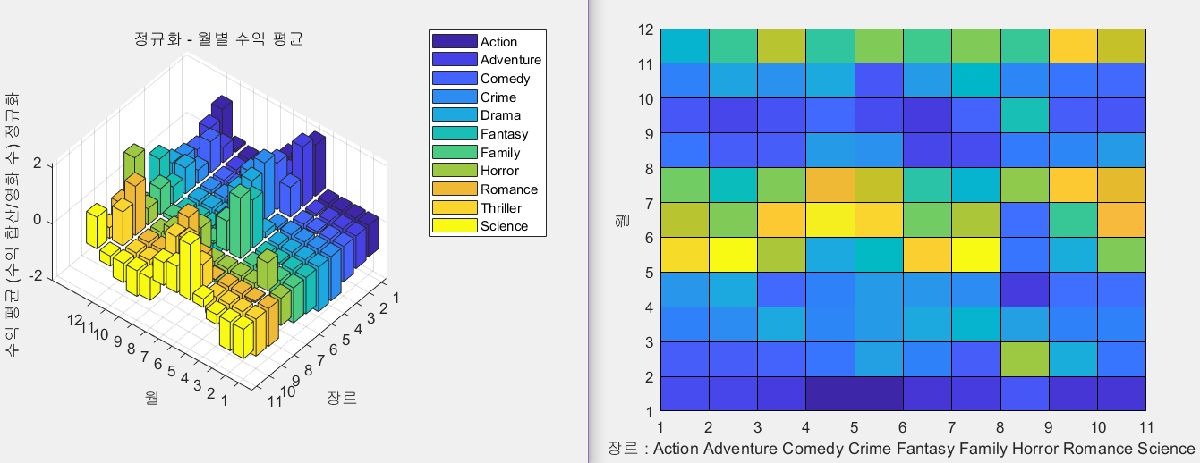

- 각 장르의 경향성 파악

5. Adventure, Horror, Romance, WantGenre의 월별 평균 수익

figure
subplot(4,1,1)
plot(AVGs(:,2),'r','linewidth',3);hold on;
title('어드벤처 영화의 월별 평균 수익');
xlabel('월')
ylabel('수익 평균 (수익 합산/영화 수)') 
hold off;

subplot(4,1,2)
plot(AVGs(:,8),'b','linewidth',3);hold on;
title('호러 영화의 월별 평균 수익');
xlabel('월')
ylabel('수익 평균 (수익 합산/영화 수)')
hold off;

subplot(4,1,3)
plot(AVGs(:,9),'m','linewidth',3);hold on;
title('로맨스 영화의 월별 평균 수익');
xlabel('월')
ylabel('수익 평균 (수익 합산/영화 수)')
hold off;

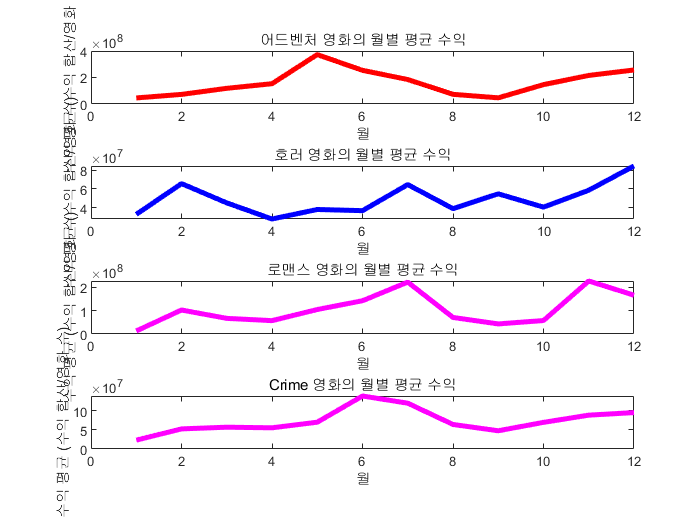

subplot(4,1,4)
plot(AVGs(:,Gindex),'m','linewidth',3);hold on;
title(WantGenre+' 영화의 월별 평균 수익');
xlabel('월')
ylabel('수익 평균 (수익 합산/영화 수)')
hold off;

## ◆ 키워드 별 수익율

WantGenre = "Crime";

- Word Cloud를 이용한 WantGenre 의 줄거리 소재 시각화

## ▶ 특정 장르의 키워드를 추출한다.

1. 해당 장르에 속하는 키워드를 추출한다.

genres = erasePunctuation(genres);
genres = erase(genres, 'id');
genres = erase(genres, 'name');
genres = regexprep(genres, '\d+(?:_(?=\d))?', '');
SpecificGenre = zeros(size(genres));
for a = 1:size(genres)
    if(contains(genres(a),WantGenre))
        SpecificGenre(a) = 1;
    end
end
Defgenres = genres;
genres = tokenizedDocument(genres);

2. 특정 장르의 Keyword data를 추출한다.

keywords = erasePunctuation(keywords);
keywords = erase(keywords, 'id');
keywords = erase(keywords, 'name');
keywords = erase(keywords, 'woman');
keywords = erase(keywords, 'independent');
keywords = erase(keywords, 'film');
keywords = erase(keywords, 'director');
keywords = regexprep(keywords, '\d+(?:_(?=\d))?', '');
keywords = tokenizedDocument(keywords);

SpecificGenre = logical(SpecificGenre);
SpecificKeywords = keywords(SpecificGenre);

3. 특정 장르의 all data를 추출한다.

DefIncome = revenue - budget; % 실 적자
DefSpecificIncome = zeros(size(DefIncome)); % 적자 = 1
DefKeyword = keywords;

for a = 1:size(DefIncome)
    if(SpecificGenre(a) == 1)
        DefSpecificIncome(a) = 1; % 특정 장르 논리값
    end
end

for a = 1:size(DefIncome)
    if(DefIncome(a) > 0)
        DefIncome(a) = 0;
    end
    if(DefIncome(a) > 0 && DefSpecificIncome(a) == 1)
        DefSpecificIncome(a) = 0;
    end
end

DefIncome(isnan(DefIncome)) = 0;
DefSpecificIncome = logical(DefSpecificIncome); 
DefKeyword = DefKeyword(DefSpecificIncome); % 적자인 키워드 추출

vote_average = vote_average(SpecificGenre);
vote_average(isnan(vote_average)) = 0;

popularity = popularity(SpecificGenre);
popularity(isnan(popularity)) = 0;

revenue = revenue(SpecificGenre);
revenue(isnan(revenue)) = 0;

budget = budget(SpecificGenre);
budget(isnan(budget)) = 0;

vote_count = vote_count(SpecificGenre);
vote_count(isnan(vote_count)) = 0;

SpecificKeywords = removeStopWords(SpecificKeywords);
SpecificKeywords = removeShortWords(SpecificKeywords, 2);
SpecificKeywords = removeLongWords(SpecificKeywords, 15);

DefKeyword = removeStopWords(DefKeyword);
DefKeyword = removeShortWords(DefKeyword, 2);
DefKeyword = removeLongWords(DefKeyword, 15);

▶ Specific Genre의 LDA Modeling 구축

1. 전체 키워드를 군집화한다.

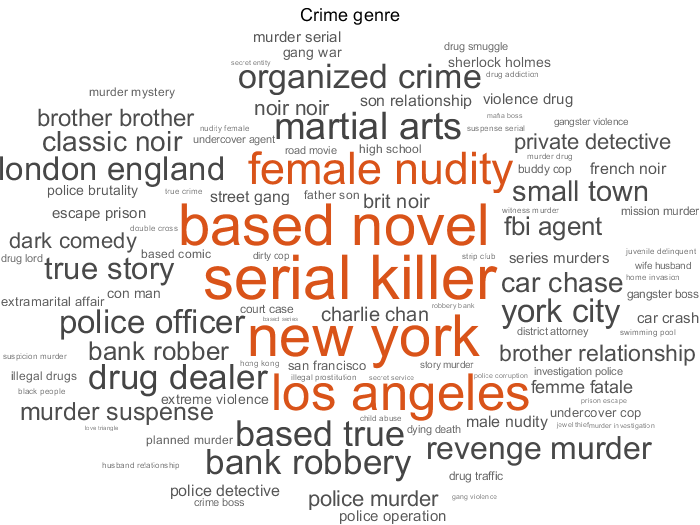

bag = bagOfNgrams(SpecificKeywords);
figure
wordcloud(bag);
title(WantGenre+" genre")

numTopics =6;
mdl = fitlda(bag,numTopics,'Verbose',0);

2. LDA Topic 별로 군집화한다.

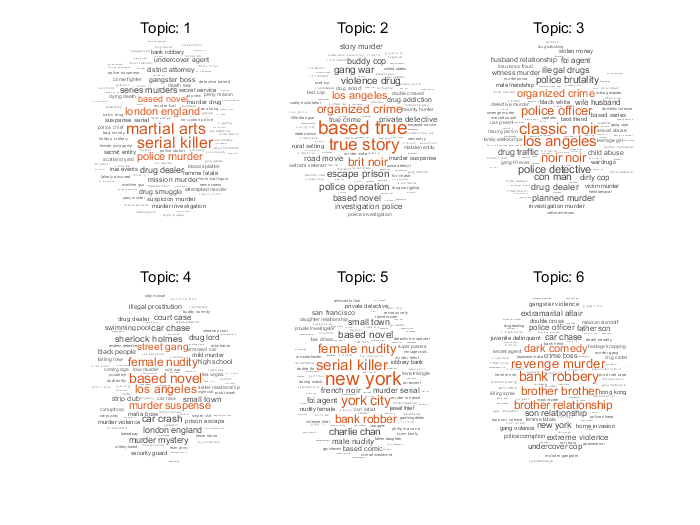

figure
for topicIdx = 1:numTopics
    subplot(2,3,topicIdx)
    wordcloud(mdl,topicIdx);
    title("Topic: " + topicIdx)
end

- 각 군집별 수익과 관람객 수의 평균 그래프

▶ Topic 군집 별 평점, 수익, 흥행도, 관람객수 평균 추출

1. 평점, 관람객수, 흥행도, 수익을 계산한다.

SpecificTopicAverage=zeros(1,numTopics);
SpecificTopicCounts=zeros(1,numTopics);
SpecificTopicPopularity=zeros(1,numTopics);
SpecificTopicRevenue=zeros(1,numTopics);
SpecificTopicMovie=zeros(1,numTopics);

for a=1:bag.NumDocuments
    if(vote_average(a,1)>0 && vote_average(a,1)<=10)
        Topic=find(mdl.DocumentTopicProbabilities(a,:)==max(mdl.DocumentTopicProbabilities(a,:)));
        SpecificTopicAverage(1,Topic)=SpecificTopicAverage(1,Topic)+vote_average(a,1);
        SpecificTopicCounts(1,Topic)=SpecificTopicCounts(1,Topic)+vote_count(a,1);
        SpecificTopicPopularity(1,Topic)=SpecificTopicPopularity(1,Topic)+popularity(a,1);
        SpecificTopicRevenue(1,Topic)=SpecificTopicRevenue(1,Topic)+revenue(a,1);
        SpecificTopicMovie(1,Topic)=SpecificTopicMovie(1,Topic)+1;
    end
end

2. 해당 군집에 속하는 영화 수를 계산한다.

for a=1:numTopics
    if(SpecificTopicMovie(1,a)~=0)
        SpecificTopicAverage(1,a)=SpecificTopicAverage(1,a)/SpecificTopicMovie(1,a);
        SpecificTopicCounts(1,a)=SpecificTopicCounts(1,a)/SpecificTopicMovie(1,a);
        SpecificTopicPopularity(1,a)=SpecificTopicPopularity(1,a)/SpecificTopicMovie(1,a);
        SpecificTopicRevenue(1,a)=SpecificTopicRevenue(1,a)/SpecificTopicMovie(1,a);
    end
end

▶ 각 그래프의 변화

1 Topic 별 흥행도 평균

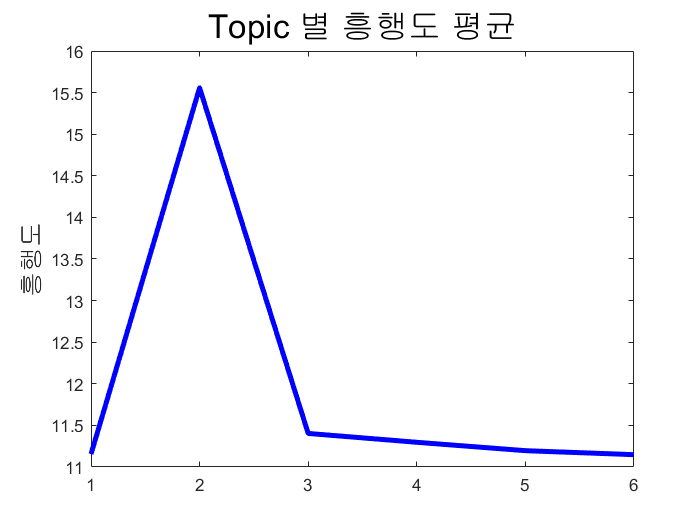

figure
plot(SpecificTopicPopularity(1,:), 'b','linewidth', 3)
xticks([1 2 3 4 5 6])
title('Topic 별 흥행도 평균','fontsize',20)
ylabel('흥행도','fontsize',15)

2. Topic 별 관람객수 평균

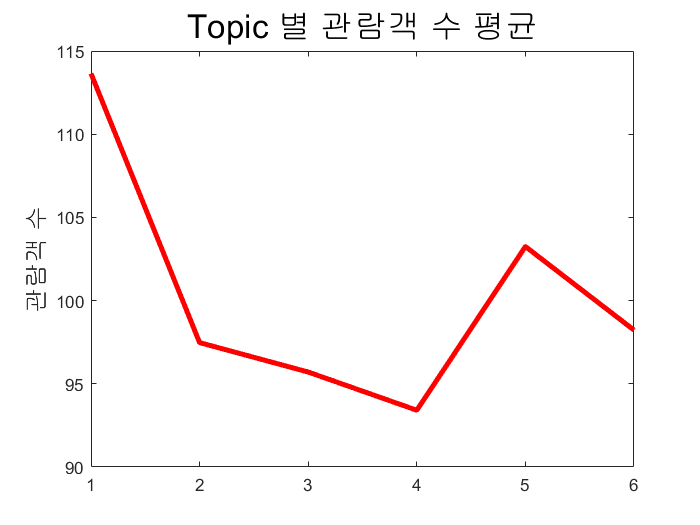

figure
plot(SpecificTopicCounts(1,:), 'r','linewidth', 3)
xticks([1 2 3 4 5 6])
title('Topic 별 관람객 수 평균','fontsize',20)
ylabel('관람객 수','fontsize',15)

3. Topic 별 평균 수익

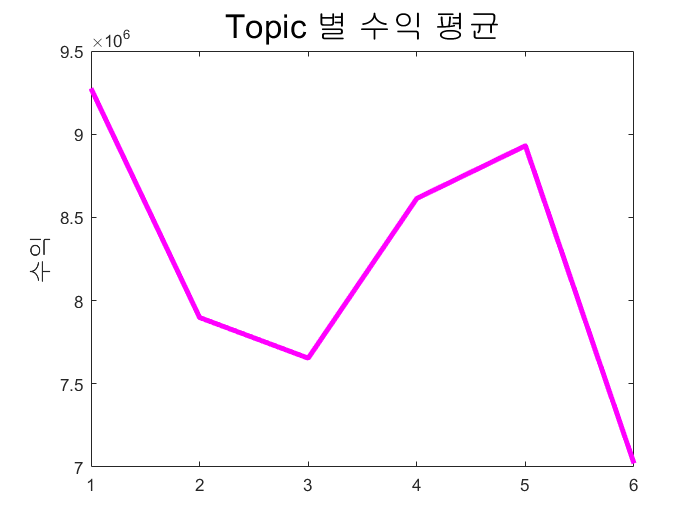

figure
plot(SpecificTopicRevenue(1,:), 'm','linewidth', 3)
xticks([1 2 3 4 5 6])
title('Topic 별 수익 평균','fontsize',20)
ylabel('수익','fontsize',15)

- Remove Outlier

▶ 해당 장르의 영화 수 추출

m = size(SpecificKeywords);
sz = m(1);

▶ 6개의 Topic 중 상위 3개 추출

TopRank = zeros(6,1);
for a = 1:numTopics
    [m,n] = max(SpecificTopicCounts);
    TopRank(a,1) = n;
    SpecificTopicCounts(n) = 0;
end

▶ Topic 군집 별 수익, 관람객수, 투자 금액 계산

test = [zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1)];
for a = 1:sz
    Topic=find(mdl.DocumentTopicProbabilities(a,:)==max(mdl.DocumentTopicProbabilities(a,:)));
    for b = 1:numTopics
        if(Topic == TopRank(b,1))
            test(a,b) = 1;
        end
    end
end

test = logical(test);
TopRevenue = [zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1)];
TopBudget = [zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1)];
TopVoteCount = [zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1)];
TopIncome = [zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1) zeros(sz,1)];

for a = 1:numTopics
    for b = 1:sz
        TopRevenue(b,a) = revenue(b)*test(b,a);
        TopBudget(b,a) = budget(b)*test(b,a);
        TopVoteCount(b,a) = vote_count(b)*test(b,a);
        TopIncome(b,a) = TopRevenue(b,a) - TopBudget(b,a);
    end
end

TopRevenue(isnan(TopRevenue)) = 0;
TopBudget(isnan(TopBudget)) = 0;
TopVoteCount(isnan(TopVoteCount)) = 0;
TopIncome(isnan(TopIncome)) = 0;

▶ Remove Outlier

1 관람객 수에 대한 이상 값 제거

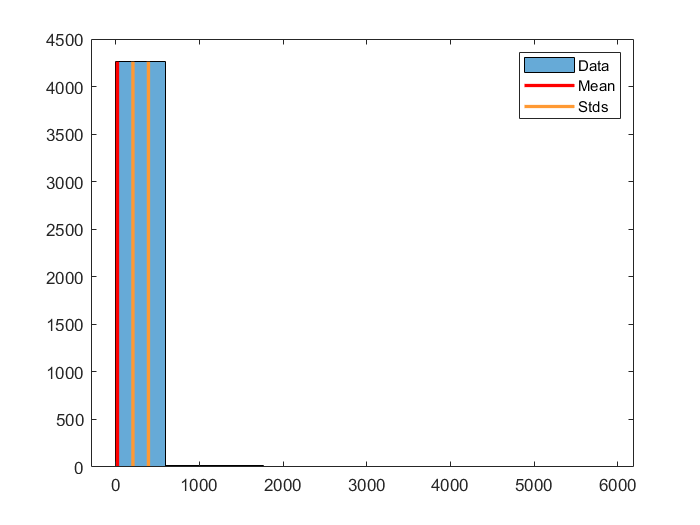

for a = 1:numTopics
    %figure % 관람객 수에 대한 이상값 제거
    h = histogram(TopVoteCount(:,a),10); % Histogram
    N = max(h.Values); % Maximum bin count
    mu3 = mean(TopVoteCount(:,a)); % Data mean
    sigma3 = std(TopVoteCount(:,a)); % Data standard deviation
    hold on
    plot([mu3 mu3],[0 N],'r','LineWidth',2); % Mean
    X = repmat(mu3+(1:2)*sigma3,2,1);
    Y = repmat([0;N],1,2);
    plot(X,Y,'Color',[255 153 51]./255,'LineWidth',2); % Standard deviations
    legend('Data','Mean','Stds');
    hold off
    outliers = (TopVoteCount(:,a) - mu3) > 4*sigma3;
    for b = 1:sz
        if(outliers(b) == 0)
            TopVoteCount(b,a) = NaN; % Add NaN values
        end
    end
end


TopVoteCount(isnan(TopVoteCount)) = 0;

- Curve Fitting

2. Income 적자 제거

for a = 1:numTopics
    for b = 1:sz
        if(TopIncome(b,a) < 0)
            TopIncome(b,a) = 0;
        end
    end
end

3. 관람객 수와 수익 데이터가 모두 존재하는 값만 추출

for a = 1:numTopics
    for b = 1:sz
        if(TopVoteCount(b,a) == 0)
            TopIncome(b,a) = 0;
        end
    end
end

for a = 1:numTopics
    for b = 1:sz
        if(TopIncome(b,a) == 0)
            TopVoteCount(b,a) = 0;
        end
    end
end

▶ Curve Fitting

    Topic 별 투표수에 따른 수익율을 Curve Fitting Plot

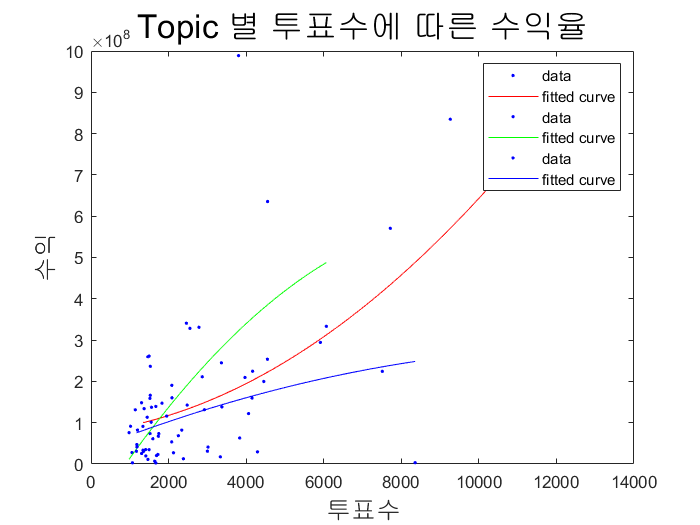

INcome = zeros(sz,1);
VC = zeros(sz,1);
color = ['r';'g';'b';'m';'k';'y'];
cnt = 0;
figure
for a = 1:numTopics
    try
        INcome = TopIncome(:,a);
        VC = TopVoteCount(:,a);
        INcome(INcome==0) = [];
        VC(VC==0) = [];
        f = fit(VC, INcome, 'poly2');
        hL1=plot(f,VC,INcome);
        set(hL1(2),'color',color(a))
        hold on
        cnt = cnt+1;
        if(cnt == 3)
            break
        end
    catch
        continue
    end
end
title('Topic 별 투표수에 따른 수익율','fontsize',20)
xlabel('투표수','fontsize',15)
ylabel('수익','fontsize',15)
hold off

▶ 상위 Topic 3개 에서 상위 25개 키워드 추출

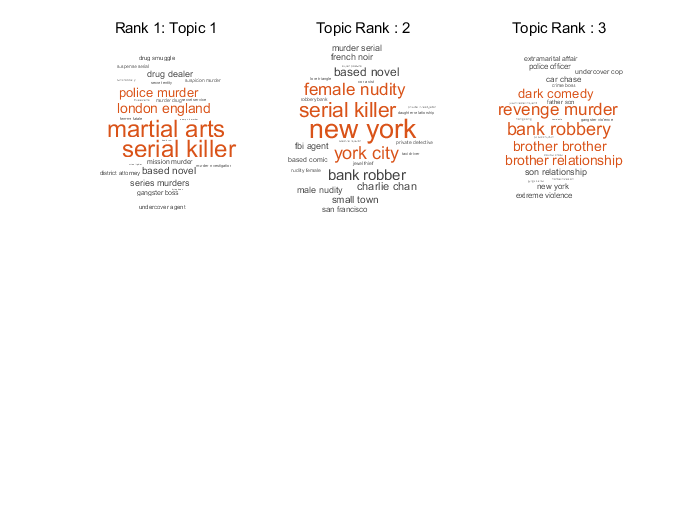

tbl1 = topkwords(mdl, 25, TopRank(1));
tbl2 = topkwords(mdl, 25, TopRank(2));
tbl3 = topkwords(mdl, 22, TopRank(3));
figure
subplot(2,3,1)
wordcloud(tbl1.Word, tbl1.Score);
title("Rank 1: Topic " + TopRank(1));
subplot(2,3,2)
wordcloud(tbl2.Word, tbl2.Score);
title("Topic Rank : 2");
subplot(2,3,3)
wordcloud(tbl3.Word, tbl3.Score);
title("Topic Rank : 3");

- 예측 대상의 줄거리 소재가 속하는 LDA Modeling

## ◆ 예측 대상의 줄거리 소재가 속하는 Topic 모델링

1. 예측 대상의 줄거리 소재가 속하는 Topic 모델링

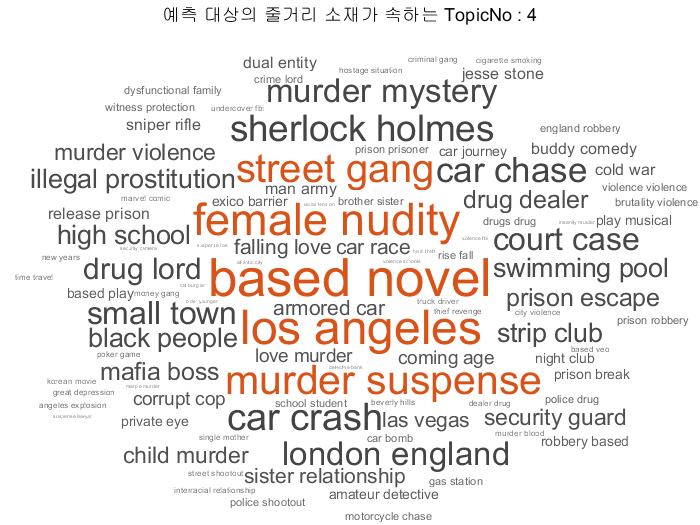

newDocuments = tokenizedDocument("new york usa women heist spin off estranged sister the met gala all female");
topicIdx = predict(mdl,newDocuments);


figure
wordcloud(mdl,topicIdx(1));
title("예측 대상의 줄거리 소재가 속하는 TopicNo : " + topicIdx(1))

2. 예측 대상의 줄거리 소재의 투표수에 따른 수익율

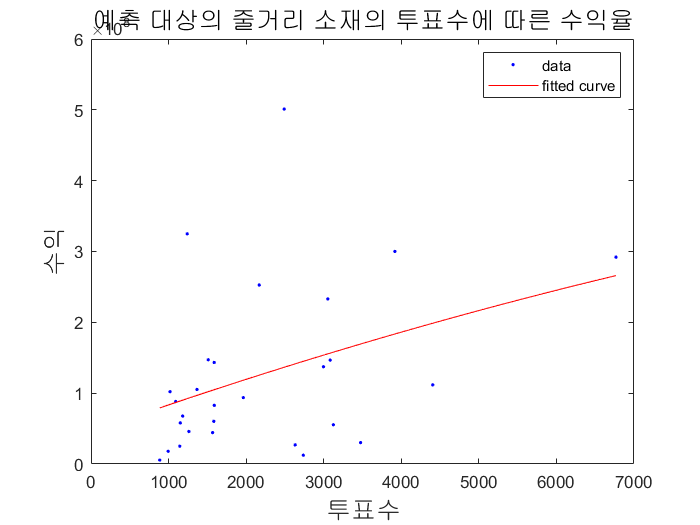

SpecificINcome = zeros(sz,1);
SpecificVC = zeros(sz,1);
figure
        SpecificINcome = TopIncome(:,topicIdx);
        SpecificVC = TopVoteCount(:,topicIdx);
        SpecificINcome(SpecificINcome==0) = [];
        SpecificVC(SpecificVC==0) = [];
        Specificf = fit(SpecificVC, SpecificINcome, 'poly2');
        SpecifichL1=plot(Specificf,SpecificVC,SpecificINcome);
        hold on
title('예측 대상의 줄거리 소재의 투표수에 따른 수익율','fontsize',15)
xlabel('투표수','fontsize',15)
ylabel('수익','fontsize',15)
hold off

3. 실제 사례

- Title : 어메이징 스파이더맨

- 순수익 : $ 5,373,268,57 ( 한국원화 : 약 6000억)

- Genre : 액션, 모험, 판타지

- Keywords : lost of loved one, experiment, vigilante, serum, based on comic, super power, spider bite, masked vigilante, reboot, genetic engineering, social outcast. duringcreditsstinger

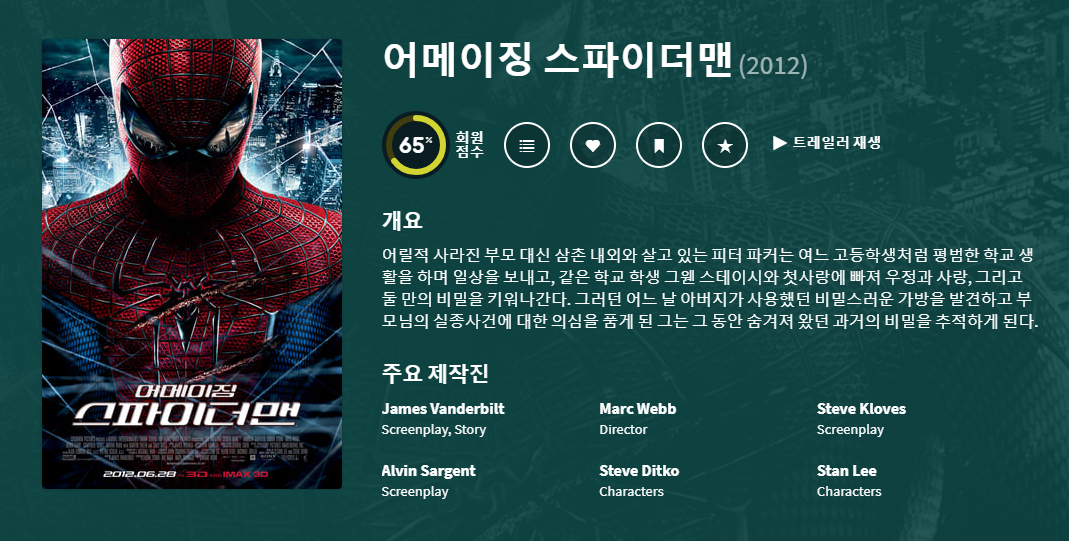

## ◆ 적자인 영화 장르 LDA 모델링

1. 특정 장르의 적자 키워드 LDA 모델링 구축

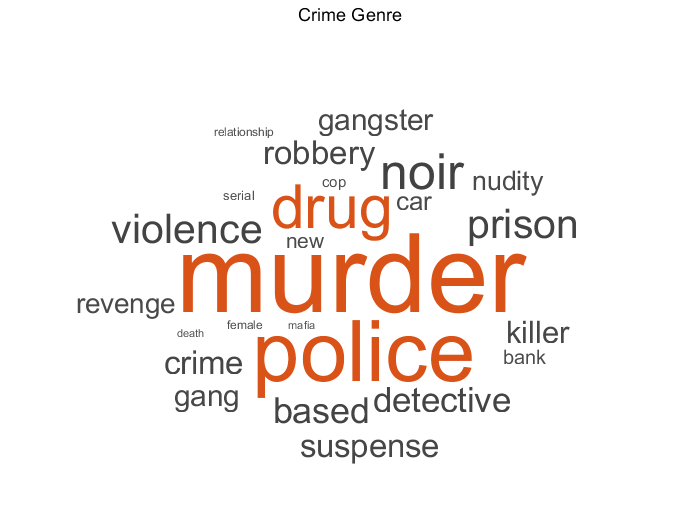

rng=('default');

bag11 = bagOfWords(DefKeyword);

mdl11 = fitlda(bag11,1,'Verbose',0);
tbl11 = topkwords(mdl11, 25, 1); %%상위 25개


figure
wordcloud(tbl11.Word, tbl11.Score);
title(WantGenre + " Genre")

2. 실제 사례

- Title : R.I.P.D : 알. 아이. 피. 디  

- 순수익 : $ -68,351,500 (한국 원화 : 약  -700억)

- Genre : 판타지, 액션, 코미디, 범죄

- Keywords : detective, gold, wife, police operation, investigation, partner, love, revenge, undead, death, husband, ghost, police department